clc; 
clear;
syms a c h x

OIF =2

OIF = 2

% OIF Order of Interpolation Function foe element
% No of elements
e = 3;
% No of Nodal points
n =e+1;

f = 4*x^2 - 2*x -4; % Source term

exact_sol_f = -2*x^2+x;

% numerical values for a, c, and h
a_num = 1;
c_num = -2;
% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;


[phi_e,nLP,Difference] = ShapeFunctions(OIF); % Gives shape functions and No of Nodal points for element

Difference = subs(Difference,h,h_num); 

% At nodel point the value of x
X = (x0:Difference:xn)';

% Local stiffness matrix
KNM_local = zeros(nLP, nLP, 'sym');
CNM_local = zeros(nLP, nLP, 'sym');

for N = 1:nLP
    for M = 1:nLP
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x) * diff(phi_e(M), x) - c * phi_e(N) * phi_e(M), x, 0, h);
        CNM_local(N, M) = int(-1* phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KNM_local);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{7\,a}{3\,h}-\frac{2\,c\,h}{15} & \sigma_{1} & \frac{c\,h}{30}+\frac{a}{3\,h}\\ \sigma_{1} & \frac{16\,a}{3\,h}-\frac{8\,c\,h}{15} & \sigma_{1}\\ \frac{c\,h}{30}+\frac{a}{3\,h} & \sigma_{1} & \frac{7\,a}{3\,h}-\frac{2\,c\,h}{15} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{c\,h}{15}-\frac{8\,a}{3\,h} \end{array}$$

disp('Local C_NM Matrix some element e:');

Local C_NM Matrix some element e:


disp(CNM_local);

$$\left(\begin{array}{ccc} -\frac{2\,h}{15} & -\frac{h}{15} & \frac{h}{30}\\ -\frac{h}{15} & -\frac{8\,h}{15} & -\frac{h}{15}\\ \frac{h}{30} & -\frac{h}{15} & -\frac{2\,h}{15} \end{array}\right)$$



% Substitute values into the local  matrices
KNM_local_sub = double(subs(KNM_local, {a, c, h}, {a_num, c_num, h_num}));
CNM_local_sub = subs(CNM_local, h, h_num);

% Display the substituted local stiffness matrix
disp('Substituted values of a c and h in Local Stiffness Matrix:');

Substituted values of a c and h in Local Stiffness Matrix:


disp(KNM_local_sub);

    7.0889   -7.9556    0.9778
   -7.9556   16.3556   -7.9556
    0.9778   -7.9556    7.0889



disp('Substituted value h in Local C_NM Matrix:');

Substituted value h in Local C_NM Matrix:


disp(CNM_local_sub);

$$\left(\begin{array}{ccc} -\frac{2}{45} & -\frac{1}{45} & \frac{1}{90}\\ -\frac{1}{45} & -\frac{8}{45} & -\frac{1}{45}\\ \frac{1}{90} & -\frac{1}{45} & -\frac{2}{45} \end{array}\right)$$



%generl formula for finding size of gloabl stiffness matrix-(S=OIF*e+1
S=OIF*e+1;
global_matrix_size = S; % each element has 2 nodal points
% Initialize global stiffness matrix


K_global = zeros(global_matrix_size);
C_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:nLP-1:S-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + nLP-1;
    K_global(start_index:end_index, start_index:end_index) = K_global(start_index:end_index, start_index:end_index) + KNM_local_sub;
    C_global(start_index:end_index, start_index:end_index) = C_global(start_index:end_index, start_index:end_index) + CNM_local_sub;
end

% Display global stiffness matrix
disp('Global Stiffness Matrix:')

Global Stiffness Matrix:


disp(K_global);

    7.0889   -7.9556    0.9778         0         0         0         0
   -7.9556   16.3556   -7.9556         0         0         0         0
    0.9778   -7.9556   14.1778   -7.9556    0.9778         0         0
         0         0   -7.9556   16.3556   -7.9556         0         0
         0         0    0.9778   -7.9556   14.1778   -7.9556    0.9778
         0         0         0         0   -7.9556   16.3556   -7.9556
         0         0         0         0    0.9778   -7.9556    7.0889



disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

   -0.0444   -0.0222    0.0111         0         0         0         0
   -0.0222   -0.1778   -0.0222         0         0         0         0
    0.0111   -0.0222   -0.0889   -0.0222    0.0111         0         0
         0         0   -0.0222   -0.1778   -0.0222         0         0
         0         0    0.0111   -0.0222   -0.0889   -0.0222    0.0111
         0         0         0         0   -0.0222   -0.1778   -0.0222
         0         0         0         0    0.0111   -0.0222   -0.0444



% Source vector Initialization 
f_x = sym(zeros(S, 1));
% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:S
    f_x(i) = subs(f, x, X(i));
end
%disp(f_x);

%K_global_inverse=InverseTDMA(K_global)

Fv = C_global*f_x; %Fvector

du_dx = -3;

% Dirichlet Boundary Conditions

K_global_D_bc = K_global;
g_x_D_bc = sym(zeros(S, 1));
GNM_D_bc= a_num*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+Fv;

% Boundary Conditions1
u0 = 0;
K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = -1;
K_global_D_bc(end,:)= [zeros(1, S-1), 1]  %un=-1

K_global_D_bc =     1.0000         0         0         0         0         0         0
   -7.9556   16.3556   -7.9556         0         0         0         0
    0.9778   -7.9556   14.1778   -7.9556    0.9778         0         0
         0         0   -7.9556   16.3556   -7.9556         0         0
         0         0    0.9778   -7.9556   14.1778   -7.9556    0.9778
         0         0         0         0   -7.9556   16.3556   -7.9556
         0         0         0         0         0         0    1.0000


RHS_D_bc(end) = un;  % RHS of equation

% % for finding inverse I'm using My TDMA inverse function
% K_global_D_bc_inverse=InverseTDMA(K_global_D_bc);

% for finding inverse I'm using My TDMA inverse function
K_global_D_bc_inverse=invLU(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc_inverse*RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point         u     
    ___________    ___________

        0                    0
        1/6            0.11111
        1/3            0.11111
        1/2        -9.4034e-17
        2/3           -0.22222
        5/6           -0.55556
        1                   -1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


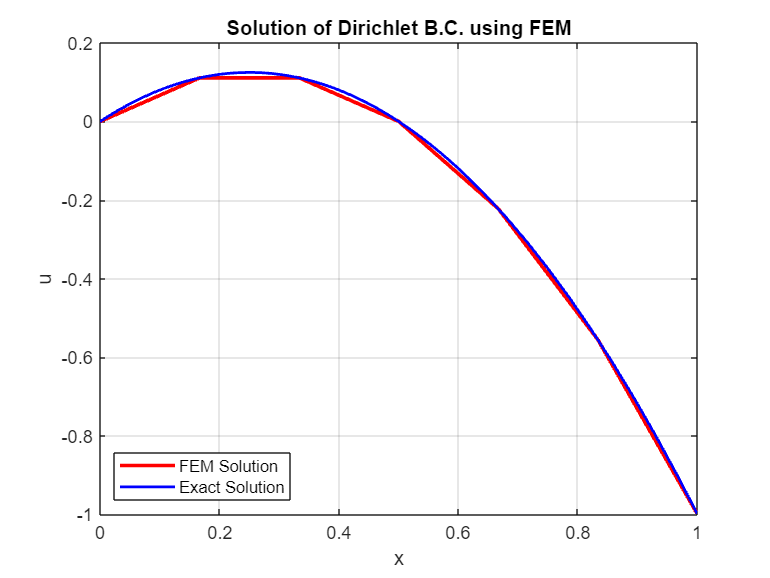

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;


du_dx = -3; % at end point x = 1

% Neumann boundary Conditions
K_global_n_bc = K_global;
g_x_n_bc = sym(zeros(S, 1));
g_x_n_bc(end)=1;

GNM_n_bc= a_num*g_x_n_bc*du_dx;
RHS_n_bc = GNM_n_bc+Fv;

% Boundary Conditions1
u0 = 0;
K_global_n_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_n_bc(1) = u0;  % RHS of equation


% % for finding inverse I'm using My TDMA inverse function
% K_global_n_bc_inverse=InverseTDMA(K_global_n_bc);
% for finding inverse I'm using My TDMA inverse function
K_global_n_bc_inverse=invLU(K_global_n_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_n_bc = double(K_global_n_bc_inverse*RHS_n_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Neumann B.C. using FEM with Phantom Node is");

The Solution of Neumann B.C. using FEM with Phantom Node is


Table2 = table(X, u_n_bc, 'VariableNames', {'Nodal point', 'u'});
disp(Table2);

    Nodal point         u     
    ___________    ___________

        0                    0
        1/6            0.11111
        1/3            0.11111
        1/2        -1.3679e-16
        2/3           -0.22222
        5/6           -0.55556
        1                   -1



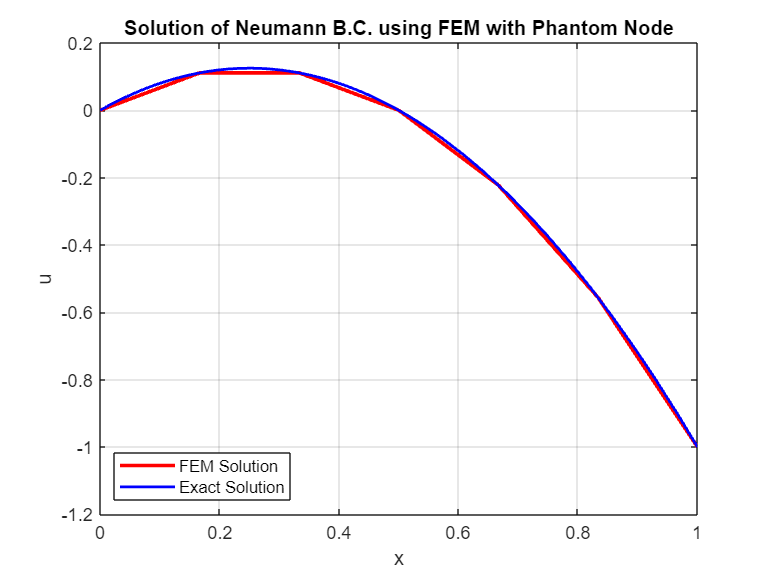


%Plot the FDM Solution and the actual solution
figure;
plot(X, u_n_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Neumann B.C. using FEM with Phantom Node");
legend('Location', 'southwest');
grid on;

function [N_sub,n,Differe] = ShapeFunctions(OIF)  % Gives shape functions and No of Nodal points for element
    syms x h;
    % OIF Order of Interpolation Function foe element
    % No of sub elements in element
    e = OIF;
    % No of Nodal points in element
    n =e+1; 
    
    x_local = sym(zeros(1, n)); % Initialize vector with zeros
    % Local Nodel points for element
    Differe = 0;
    for i = 1:n
        x_local(i) = (i-1)*h/e; % Calculate the elements of the vector
        if i ==2
        Differe = (i-1)*h/e;
        end
    end
    
    %disp(x_local); % Display the vector
    
    x_string = sym('x', [1 n]);
    
    N = sym(zeros(size(x_string)));
    
    % Generating Lagrange interpolating polynomial
    for j = 1:n
        % Compute the product term for each j
        product_term = 1;
        for k = 1:n
            if k ~= j
                product_term = product_term * (x - x_string(k)) / (x_string(j) - x_string(k));
            end
        end
    
        N(j)=product_term;
    end
    
    N_sub = subs(N,x_string,x_local);
end

function [A_inverse] = invLU(A)
%CroutsLU
    [m, n] = size(A);
    if m ~= n
        error('Input matrix must be square');
    end
    
    U = eye(n);  % Initialize L as identity matrix
    L = zeros(n); % Initialize U as zero matrix
    L(:,1) = A(:,1);
    U(1,:) = A(1,:)/L(1,1);

    for i = 2:n

        % Computing elements of L
        for k = i:n
            L(k, i) = A(k, i) - L(k, 1:i-1) * U(1:i-1, i);
        end

        %  Computing elements of U
        for j = i+1:n
            U(i, j) = (A(i, j) - L(i, 1:i-1) * U(1:i-1, j))/L(i,i);
        end

    end

    [n, ~] = size(L);
    % Identity matrix for b
    b = eye(n);
    
    x = zeros(n, n);
    
    % Solve Ly = b and then Ux = y for each column of b
    for col = 1:n
        y = zeros(n, 1);
    
        % Solve Ly = b (forward substitution)
        y(1) = b(1, col) / L(1, 1);
        for i = 2:n
            sum = b(i, col);
            for j = 1:i-1
                sum = sum - L(i, j) * y(j);
            end
            y(i) = sum / L(i, i);
        end
    
        % Solve Ux = y (backward substitution)
        x(n, col) = y(n);
        for i = n-1:-1:1
            sum = y(i);
            for j = i+1:n
                sum = sum - U(i, j) * x(j, col);
            end
            x(i, col) = sum / U(i, i);
        end
    end
    % Now,in  this x matrix contains the columns of the inverse of A
    A_inverse = x;
end
